# Extended Kalman Filter

clearvars, clc;

## Read Data

T = readtable('_LMParameters.txt', 'FileType', 'text', 'Delimiter', '\t');
data = readmatrix('A1-007-DST-US06-FUDS-25-20120827.xlsx', 'Sheet', 'Sheet1');
M = readmatrix('_polynomialEstimate.txt', 'FileType','text', 'Delimiter','\t', 'NumHeaderLines', 1);

## Initialization

R0 = T.R0;
R1 = T.R1;
R2 = T.R2;
C1 = T.C1;
C2 = T.C2;
Uoc = T.Uoc;

best_coeffs_chg = M(:,2).';

Ut = data(:,5)';
I = data(:,4)';
N = length(I);
TestTime = data(:,1)';
dt = diff(TestTime);
dt(end+1) = dt(end);

Cn = 1.1;

xHat = zeros(3, N);             % State estimate: [U1; U2; SOC]
xHat(:,1) = [0; 0; 1];          % Inisialisasi: U1=0, U2=0, SOC=100%
P = eye(3);                     % Covariance matrix
Q = diag([1e-6, 1e-6, 1e-7]);   % Covariance noise proses
R = 1e-6;                       % Covariance noise observasi

## Looping

for k = 2:N
    curR0 = R0(k);
    curR1 = R1(k);
    curR2 = R2(k);
    curC1 = C1(k);
    curC2 = C2(k);

    if ~isfinite(curR0)
        curR0 = 1e12;
    end

    if ~isfinite(curR1)
        curR1 = 1e12;
    end

    if ~isfinite(curR2)
        curR2 = 1e12;
    end

    if ~isfinite(curC1)
        curC1 = 1e12;
    end

    if ~isfinite(curC2)
        curC2 = 1e12;
    end

    % Matriks transisi state (linierasi)
    A = [
            exp(-dt(k)/(curC1 * curR1)),    0,                              0; 
            0,                              exp(-dt(k)/(curC2 * curR2)),    0;
            0,                              0,                              1;
    ];

    B = [
        curR1*(1 - exp(-dt(k)/(curC1 * curR1))); 
        curR2*(1 - exp(-dt(k)/(curC2 * curR2))); 
        -dt(k)/(Cn * 3600)
    ];
    
    % State sebelumnya
    SOC_prev = xHat(3,k-1);
    
    % Hitung Jacobian matriks output C
    dUoc = dUocCurve(SOC_prev);
    C = [-1, -1, dUoc];
    D = -curR0;
    
    % Prediksi state dan kovarians
    x_pred = A * xHat(:,k-1) + B * I(k-1);
    P_pred = A * P * A' + Q;
    
    % Hitung Kalman gain
    K = P_pred * C' / (C * P_pred * C' + R);
    
    % Update state dan kovarians
    y_pred = C*x_pred + D*I(k);
    xHat(:,k) = x_pred + K * (Ut(k) - y_pred);
    xHat(3,k) = max(0, min(1, xHat(3,k)));

    P = (eye(3) - K * C) * P_pred;
end

## Coulomb Counting

SOC = zeros(1, N);
SOC(1) = 1;

for k = 2:N
    SOC(k) = SOC(k-1) - (I(k) * dt(k)) / (Cn * 3600);
    SOC(k) = max(0, min(1, SOC(k)));
end

## Graphing Data

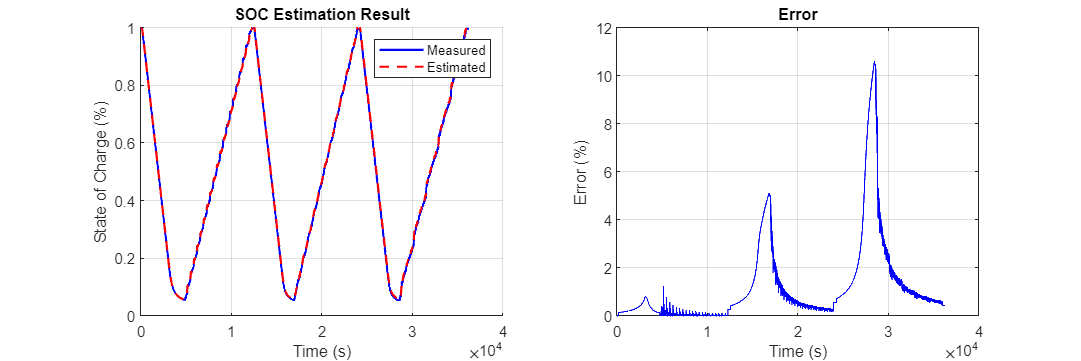

figure;
set(gcf, 'Position', [100, 100, 1200, 400]);

subplot(1,2,1);
hold on;
plot(TestTime, SOC, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Measured'); 
plot(TestTime, xHat(3, :), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Estimated');
xlabel('Time (s)');
ylabel('State of Charge (%)');
title('SOC Estimation Result');
legend;
grid on;
hold off;

subplot(1,2,2);
plot(TestTime, 100 * abs(xHat(3,:) - SOC) ./ SOC, 'b');
xlabel('Time (s)');
ylabel('Error (%)');
title('Error');
grid on;

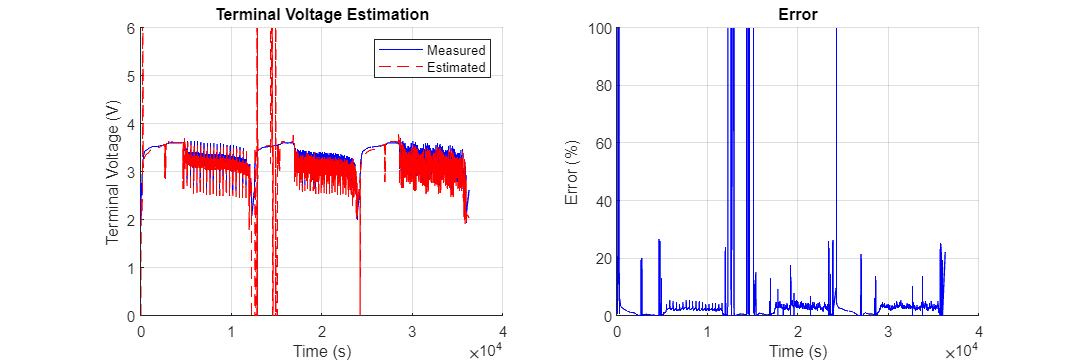

% Terminal Voltage

Ut_est = UocCurve(xHat(3,:)) - ( R0' .* I + xHat(1,:) + xHat(2,:) );

figure;
set(gcf, 'Position', [100, 100, 1200, 400]);

subplot(1,2,1);
hold on;
plot(TestTime, Ut,     'b',  'DisplayName','Measured'); 
plot(TestTime, Ut_est, 'r--','DisplayName','Estimated');
xlabel('Time (s)');
ylabel('Terminal Voltage (V)');
title('Terminal Voltage Estimation');
legend;
ylim([0, 6]);
grid on;

subplot(1,2,2);
hold on;
plot(TestTime, 100 * abs(Ut - Ut_est) ./ Ut, 'b'); 
xlabel('Time (s)');
ylabel('Error (%)');
title('Error');
ylim([0, 100]);
grid on;